# Week 1 Practical: Decay as a Computational Experiment

This is the **PHY4605 Physics-First Reproducible MATLAB Notebook** for a group investigation. It is a starter, not a solution sheet. Complete the prediction prompts and replace each TODO with your group's own work.

The investigation question is: how small must the timestep be before Forward Euler is accurate enough and physically admissible for a chosen decay experiment?

Run this Live Script from a fresh MATLAB session. Keep units visible in names and record every parameter change.

## Model Visual

The embedded visual connects the physical system, differential equation, and expected decay trend. Use it to orient your prediction; the practical work begins when you test the scale, timestep, and numerical approximation yourself.

## Physical Question and Learning Outcome

We model a radioactive sample with $dN/dt=-\lambda N$, where $N$ is an amount of undecayed material and $\lambda=\ln(2)/T_{half}$. By the end, your group should be able to justify a timestep using scale, error, validation, and physical interpretation.

**Question 1 — model statement:** In your own words, state what $N$, $N_0$, $T_{half}$, $\lambda$, $t$, and $dt$ mean. Include units for every dimensional quantity.

## Prediction Before Computing

Complete Questions 2–4 in the Entry Check before running the calculation. Do not silently replace a prediction with a computed value: record the prediction first, then compare it with evidence.

**Question 2 — scale:** Predict the fraction remaining after one half-life and after four half-lives. Explain the pattern.

**Question 3 — dimensionless step:** Predict what the size of $\lambda dt$ tells you about the numerical update.

**Question 4 — failure mode:** Predict what may happen when $\lambda dt>1$. State whether the result would still be physically admissible.

## Model, Parameters, and Units

Start with the baseline values below. Change them only after you have a validated baseline. The parameter block is deliberately visible so that another person can reproduce your experiment.

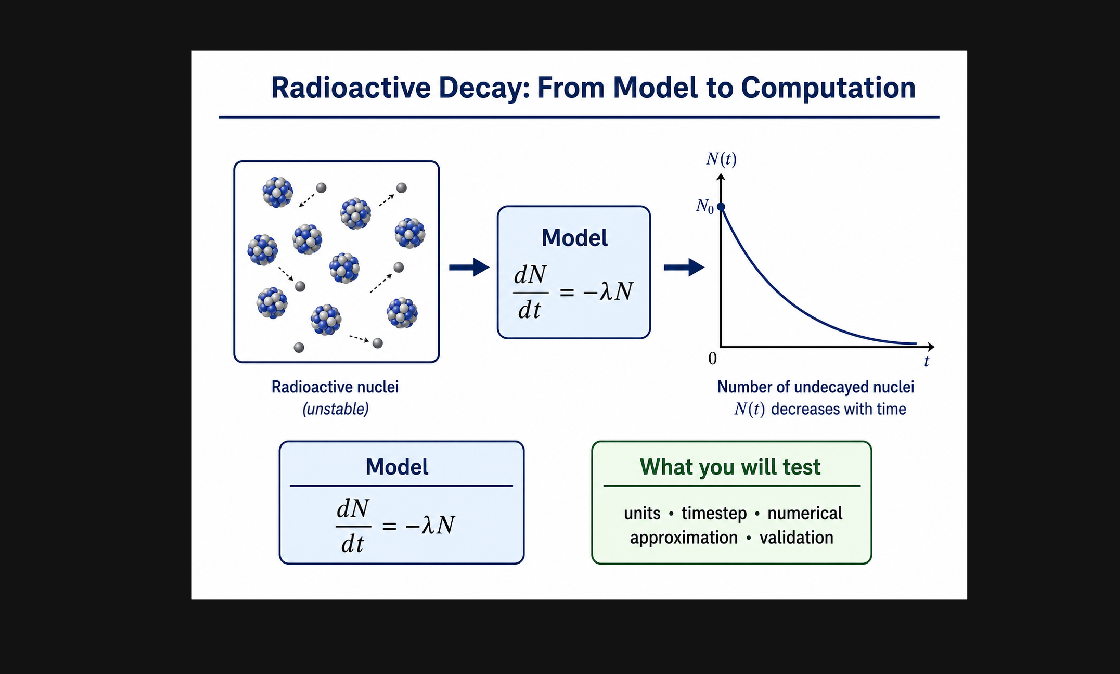

clearvars
format shortG
N0 = 1000;                 % initial amount, nuclei or arbitrary amount
T_half_h = 6.0;            % half-life, h
tMax_h = 24.0;             % final time, h
dt_h = 0.5;                % proposed Euler timestep, h
lambda_per_h = log(2)/T_half_h;  % decay constant, 1/h

lambdaDt = lambda_per_h*dt_h;    % dimensionless timestep
parameterRecord = table(N0,T_half_h,tMax_h,dt_h,lambda_per_h,lambdaDt);
disp(parameterRecord)

## Reference Model and Numerical Grid

The exact expression is a reference for checking the numerical experiment. The grid below uses the chosen timestep; verify that it reaches the requested final time exactly.

t_h = 0:dt_h:tMax_h;
N_exact = N0*exp(-lambda_per_h*t_h);

**Question 5 — discretisation:** Add a check or a displayed statement showing the number of steps and whether the final grid time equals `tMax_h`. Explain why a grid that misses the requested final time would weaken a comparison.

stepCount = numel(t_h) - 1;
disp(table(stepCount,t_h(end),tMax_h,'VariableNames',{'steps','gridFinal_h','requestedFinal_h'}))
assert(abs(t_h(end)-tMax_h) < 100*eps(max(1,tMax_h)), ...
    'The time grid does not reach tMax_h exactly.')

## Forward Euler Scaffold

The update is $N_{k+1}=N_k(1-\lambda dt)$. The array is initialised but the step loop is intentionally left for your group. Your completed loop should use the previous value to calculate the next value and should not call the exact solution.

N_euler = nan(size(t_h));
N_euler(1) = N0;
% TODO Question 6: write the Forward Euler loop here.
% Example structure to complete: for k = 1:numel(t_h)-1 ... end

     N0     T_half_h    tMax_h    dt_h    lambda_per_h    lambdaDt
    ____    ________    ______    ____    ____________    ________

    1000       6          24      0.5       0.11552       0.057762



if any(isnan(N_euler))
    disp('Question 6 is still open: complete the Forward Euler loop.')
else
    figure('Name','Euler and exact reference')
    plot(t_h,N_euler/N0,'o-',t_h,N_exact/N0,'k-','LineWidth',1.4)
    grid on
    xlabel('Time, t (h)')
    ylabel('Fraction remaining, N/N_0')

    steps    gridFinal_h    requestedFinal_h
    _____    ___________    ________________

     48          24                24       



    title('Forward Euler and exact reference')
    legend('Forward Euler','Exact reference','Location','northeast')
end

## Error and Physical Admissibility

Compare the completed Euler result with the reference at the same times. Use a relative error when the reference value is non-zero, and check whether the computed amount stays non-negative.

**Question 7 — error evidence:** Calculate the final relative error and one additional error measure of your choice. State which one you will use to accept or reject `dt_h`.

**Question 8 — physical check:** Add an executable check for non-negative amount and explain what the condition means physically.

if any(isnan(N_euler))
    disp('Questions 7 and 8 are waiting for your completed Euler result.')
else
    finalRelativeError = abs(N_euler(end)-N_exact(end))/abs(N_exact(end));
    maxRelativeError = max(abs(N_euler-N_exact)./max(abs(N_exact),eps));
    disp(table(finalRelativeError,maxRelativeError,'VariableNames', ...
        {'finalRelativeError','maxRelativeError'}))
    assert(all(isfinite(N_euler)),'The numerical result is not finite.')
    assert(all(N_euler >= 0),'The numerical result is not physically admissible.')
end

Question 6 is still open: complete the Forward Euler loop.


## Timestep Investigation

A single successful run cannot show convergence. Use at least four values of `dt_h`, including one coarser and one finer value than the baseline. Keep `T_half_h`, `N0`, and `tMax_h` fixed during this comparison.

**Question 9 — convergence:** Build a table with timestep, `lambda*dt`, step count, final Euler fraction, and relative error. Plot the numerical curves against the exact reference. Describe the trend you observe and identify a timestep you would trust.

dtValues_h = [2.0 1.0 0.5 0.1];
convergenceTable = table(dtValues_h(:),lambda_per_h*dtValues_h(:), ...
    'VariableNames',{'dt_h','lambdaDt'});
% TODO Question 9: add your loop, error columns, validation check, and labelled plot.
disp(convergenceTable)

Questions 7 and 8 are waiting for your completed Euler result.


    dt_h    lambdaDt
    ____    ________

      2      0.23105
      1      0.11552
    0.5     0.057762
    0.1     0.011552



## Submission Evidence

Your group submission must contain the completed Live Script and the evidence below:

- a prediction record with parameters, units, and expected trends;

- a labelled Forward Euler versus exact-reference plot;

- a timestep comparison or convergence plot and a table containing `dt`, `lambda*dt`, step count, final value, and error;

- executable validation checks for a known value and physical admissibility or limiting behaviour;

- a quantitative timestep justification, physical interpretation, model or method limitation, individual contribution record, and AI declaration.

## Physical Interpretation and Individual Accountability

**Question 10 — interpretation:** Write a short paragraph answering the investigation question. Refer to scale and units, the numerical update, quantitative error, physical admissibility, and one limitation of the decay model or Forward Euler method.

Add an individual contribution record below the paragraph. Each student must name one section they wrote or tested and explain one code or physics decision without reading another student's explanation.

Group interpretation: ____________________________________________________________________________________

Individual contribution record: ___________________________________________________________________________

Student name(s): _______________________________________________________________________________________

## Exit Ticket and AI Declaration

Before submission, answer these prompts in the Live Script:

- What evidence makes your chosen timestep acceptable?

- Which validation check would fail first if the timestep became too large?

- What did you learn from the disagreement between prediction and computation, if any?

AI declaration: state **AI-free** or name each AI tool used, the date, the purpose, and the code or text it influenced. List the independent checks your group performed: units, limiting case, timestep/convergence, admissibility, and physical interpretation.

Reproducibility record: MATLAB release, parameter values, timestep values, validation outcomes, and any known limitation.